# Import Signal Labels

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code creates the signals into a datastore. 

pathToSignals = "../data/flooddata";
varnames = ["ax" "ay" "az"];
sigds = signalDatastore(pathToSignals, "IncludeSubfolders", true, "SignalVariableNames", varnames, "ReadOutputOrientation", "row")

sigds =   signalDatastore with properties:

                       Files:{
                             ' .../Deep_Learning_with_MATLAB/data/flooddata/depth_0_0/exp1.csv';
                             ' .../Deep_Learning_with_MATLAB/data/flooddata/depth_0_0/exp10.csv';
                             ' .../Deep_Learning_with_MATLAB/data/flooddata/depth_0_0/exp11.csv'
                              ... and 219 more
                             }
                     Folders: {'/home/luis-mendoza/Documents/GitHub/MATLAB_Courses/Deep_Learning_with_MATLAB/data/flooddata'}
    AlternateFileSystemRoots: [0×0 string]
                    ReadSize: 1
         SignalVariableNames: ["ax"    "ay"    "az"]
       ReadOutputOrientation: "row"


## Task 1

You have used a `signalDatastore` to access the data set. To train a network that can classify your signals, your data needs to be labeled. The location of these labels will depend on your data set.

Each signal in the flood data set is stored in a folder according to its class. To get the labels for each signal, you can use the `folders2labels` function.

`lbs` `=` `folders2labels``(``"``folder``"``)`

labels = folders2labels(pathToSignals)

labels = 222×1 categorical array
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 
     depth_0_0 


## Task 2

The variable `labels` contains a *categorical* vector. You can use the `summary` function with categorical data to see what labels are your data set and the number of signals per class.

`lbs` `=` `folders2labels``(``"``folder``"``)`

`summary``(``lbs``)`

summary(labels)

     depth_0_0        33 
     depth_0_19       53 
     depth_2_5        34 
     depth_4_5       102 


## Task 3

In the summary, you can see the number of signals in each class. The class labels come from the subfolder names, which correspond to the depth of water that the volunteer walked through while their smartphone data was recorded.

When you classify with your trained deep network, these are the classes that the network will use. You might want to make changes to the labels before training your network. For example, you can combine similar classes into one class with the `mergecats` function. For the flood data set, using the class names below could be more descriptive. You can rename the classes with the `renamecats` function.

`lbls` `=` `renamecats``(``lbls``,``[``"class1"` `"class2"``])`

labels = renamecats(labels, ["0.0 ft" "0.19 ft" "2.5 ft" "4.5 ft"]);
summary(labels)

     0.0 ft        33 
     0.19 ft       53 
     2.5 ft        34 
     4.5 ft       102 


## Task 4

Now that you've labeled the data set, you can look at a signal from each of the four flooding depths. You can use the `unique` function with two outputs to find a signal from each class.

`[``lb``,``idx``]` `=` `unique``(``lbs``)`

`lb` contains the name of your classes and `idx` contains the first index for each class.

Then you can use the `subset` function on the signal datastore to extract the signals at those indices.

`dsidx` `=` `subset``(``sigds``,``idx``)`

[labels4, idx] = unique(labels)

labels4 = 4×1 categorical array
     0.0 ft 
     0.19 ft 
     2.5 ft 
     4.5 ft 


idx =      1
    34
    87
   121


ds4 = subset(sigds, idx)

ds4 =   signalDatastore with properties:

                       Files:{
                             ' .../Deep_Learning_with_MATLAB/data/flooddata/depth_0_0/exp1.csv';
                             ' .../Deep_Learning_with_MATLAB/data/flooddata/depth_0_19/exp1.csv';
                             ' .../Deep_Learning_with_MATLAB/data/flooddata/depth_2_5/exp1.csv'
                              ... and 1 more
                             }
                     Folders: {'/home/luis-mendoza/Documents/GitHub/MATLAB_Courses/Deep_Learning_with_MATLAB/data/flooddata'}
    AlternateFileSystemRoots: [0×0 string]
                    ReadSize: 1
         SignalVariableNames: ["ax"    "ay"    "az"]
       ReadOutputOrientation: "row"


## Task 5

Now you have a signal datastore that points to four files, corresponding to the four flooding depths. To view the signals, you need to import the signals from the files to the Workspace.

To import all the signals from a datastore, use the `readall` function.

`data` `=` `readall``(``ds``)`

sig4 = readall(ds4)

sig4 = 4×1 cell array
    {1×3 cell}
    {1×3 cell}
    {1×3 cell}
    {1×3 cell}


## Visualize the signals

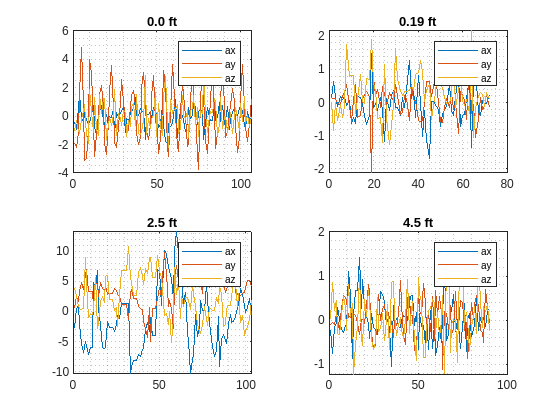

visdataset(sig4, labels4)

function visdataset(data, labels)
    figure
    tiledlayout(2, 2)
    for k = 1:4
        nexttile
        plot(cell2mat(data{k}))
        grid minor
        title(labels(k))
        legend(["ax" "ay" "az"])
    end
end